1. Формирование синусоидального сигнала

clear
A = 1;
w = 2 * pi * 10;
Fs = 1000;
t = 0 : 1 / Fs : 10;
S = A * sin(w * t);
f = (0 : (length(S) - 1)) * Fs / length(S);

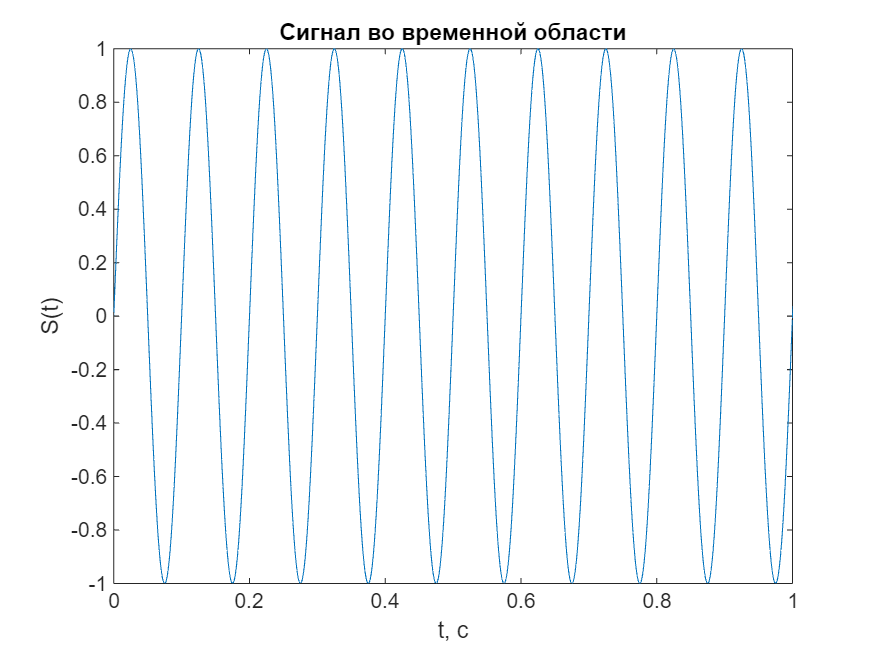

plot(t, S)
title("Сигнал во временной области")
xlabel("t, с")
ylabel("S(t)")
xlim([0, 1])

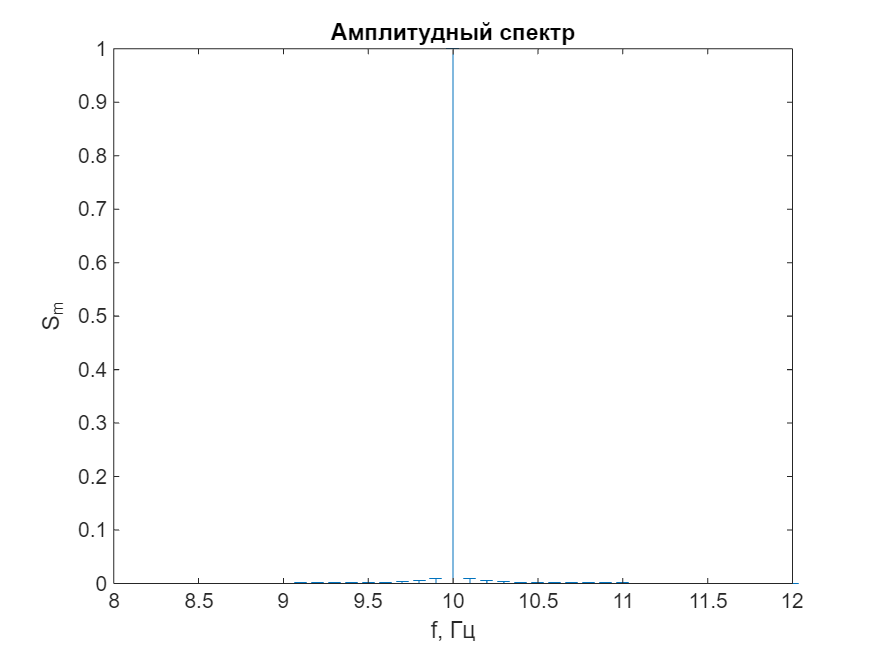

S_FFT = fft(S);
ampl = abs(S_FFT) / length(S) * 2;
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр")
ylabel("S_m")
xlabel("f, Гц")
xlim([8,12])

2. Добавление синусоидального шума

nA = 0.1;
nw = 2 * pi * 1;
noise = nA * sin(nw * t);
Sn = S + noise;

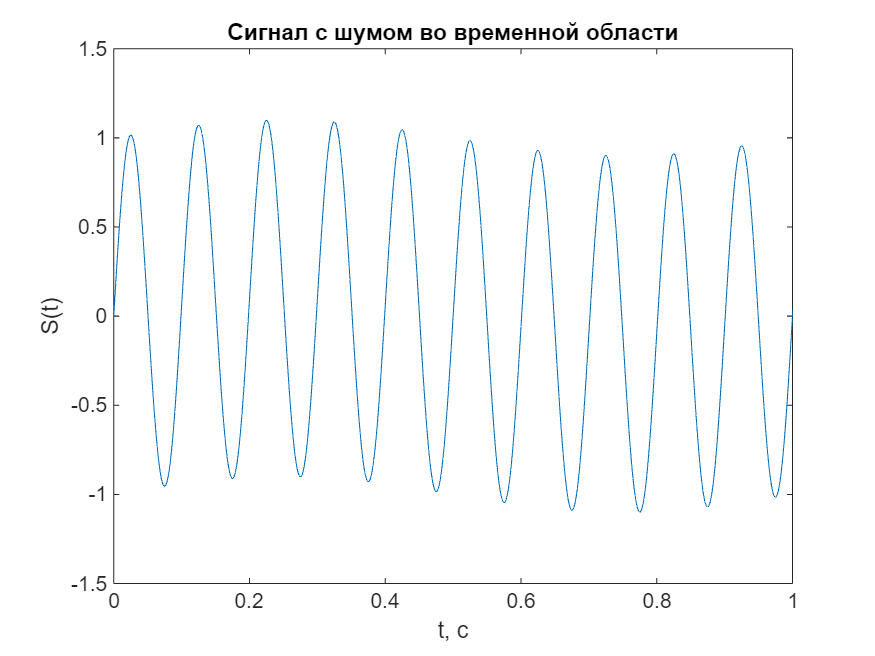

plot(t, Sn)
title("Сигнал с шумом во временной области")
xlabel("t, с")
ylabel("S(t)")
xlim([0,1])

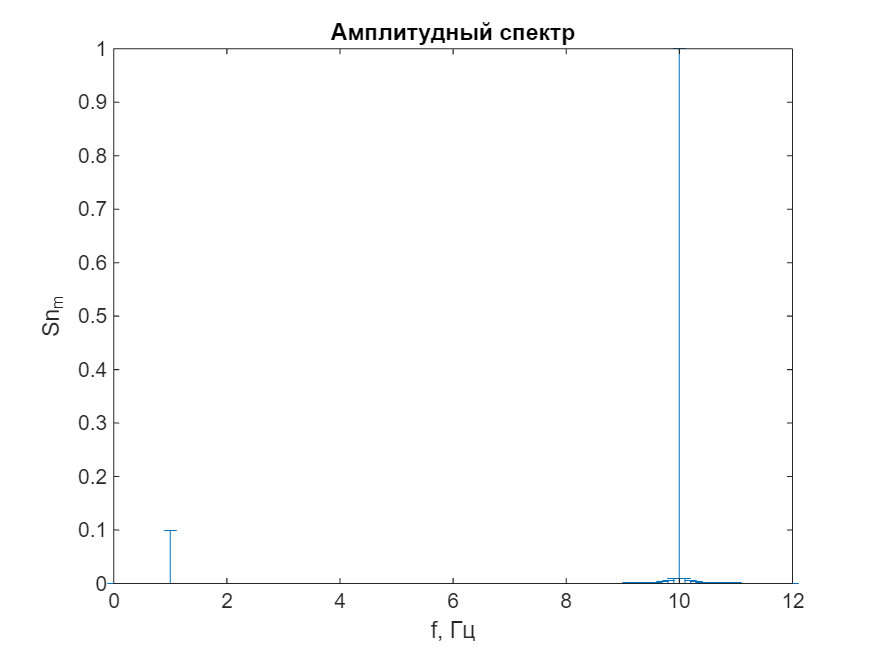

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn) * 2;
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,12])

3. Синтезирование КИХ-фильтра

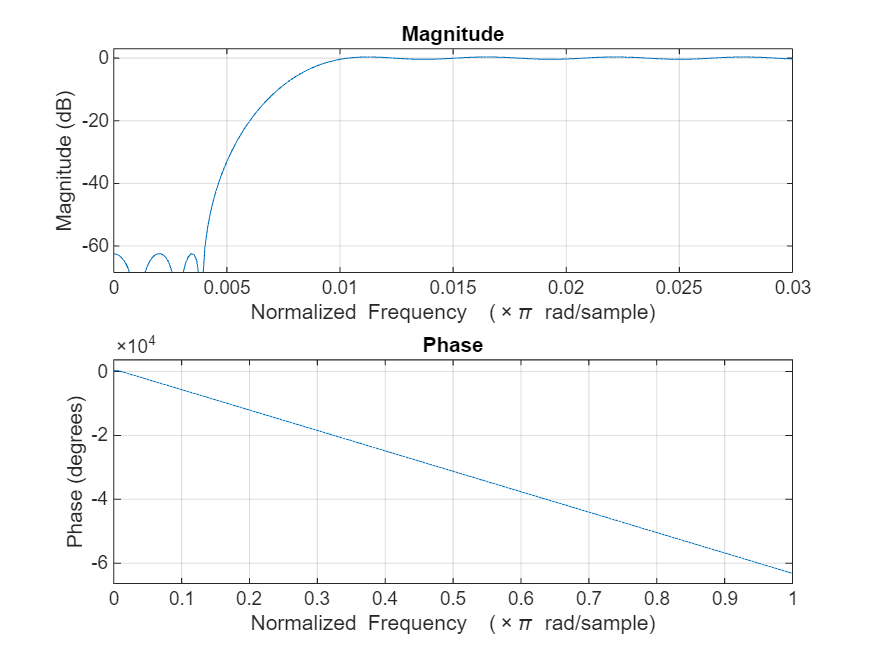

FIR = firFilter();
FIR.freqz
xlim([0, 0.03])

FIR.order

ans = 710

4. Применение фильтра

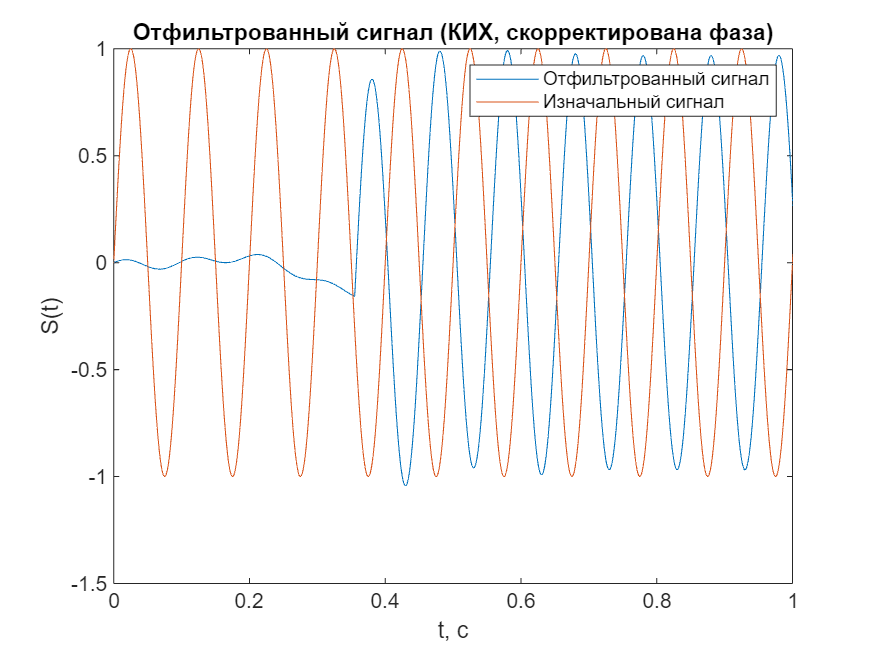

newS = filter(FIR,Sn);
plot(t, newS)
hold on
plot(t, A * sin(w * t))
hold off
title("Отфильтрованный сигнал (КИХ, скорректирована фаза)")
xlabel("t, с")
ylabel("S(t)")
legend("Отфильтрованный сигнал", "Изначальный сигнал")
xlim([0,1])

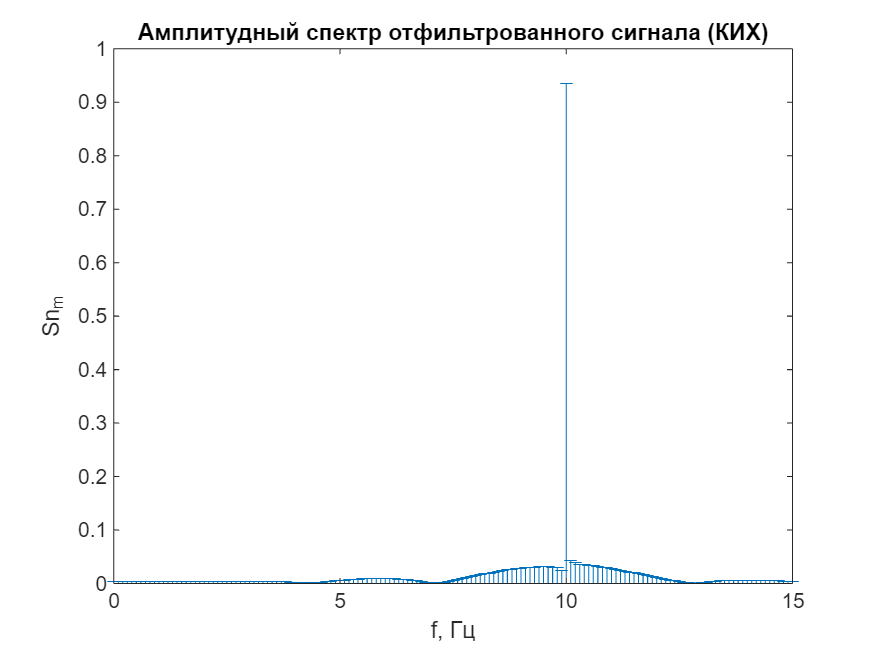

newPhase = 559/180*pi;
newS_FFT = fft(newS);
ampl = abs(newS_FFT) / length(newS_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.05; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(newS_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала (КИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

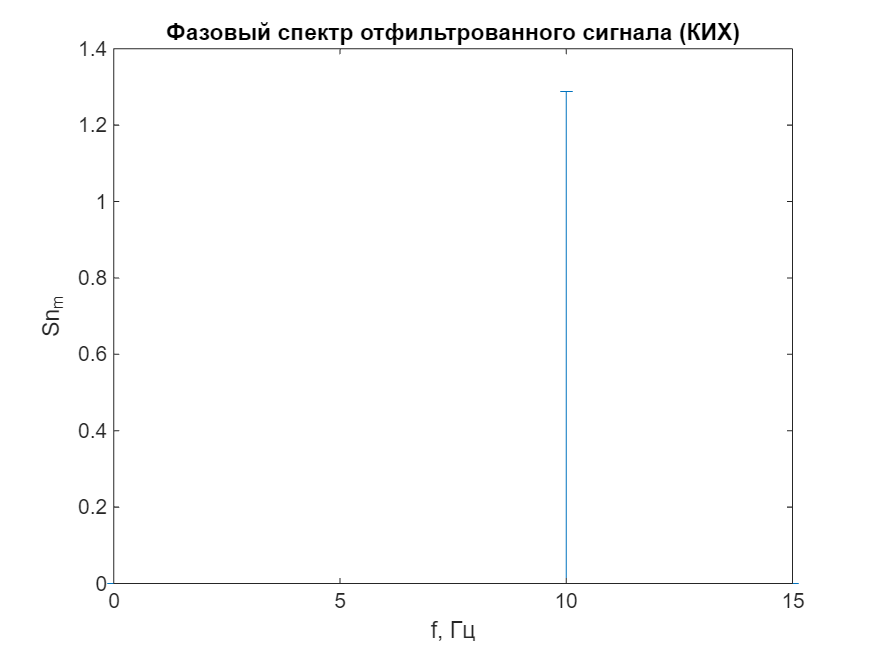

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала (КИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

5. Синтезирование БИХ-фильтра

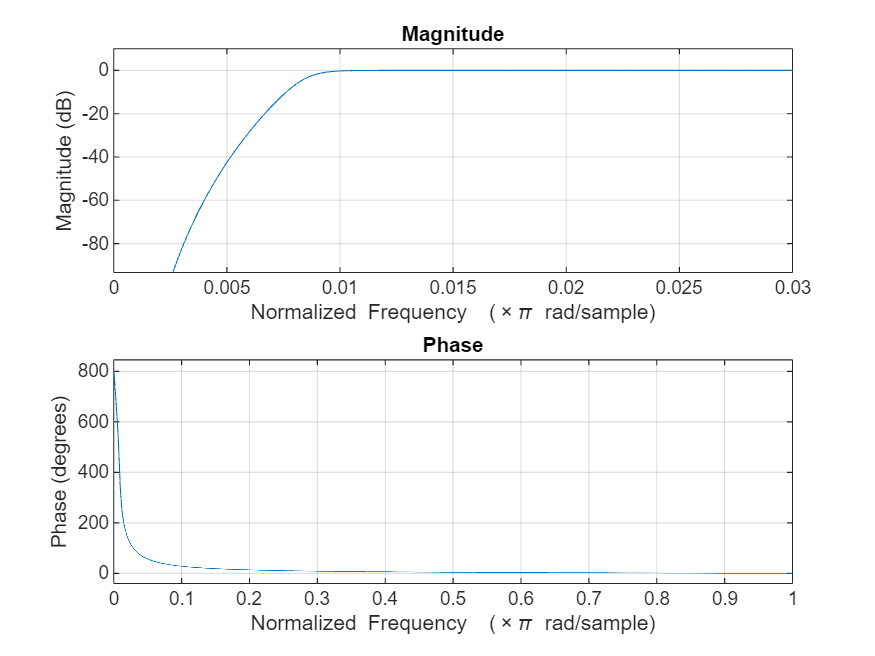

IIR = iirFilter();
IIR.freqz
xlim([0, 0.03])

IIR.order

ans = 9

% 145.2 deg

6. Применение фильтра

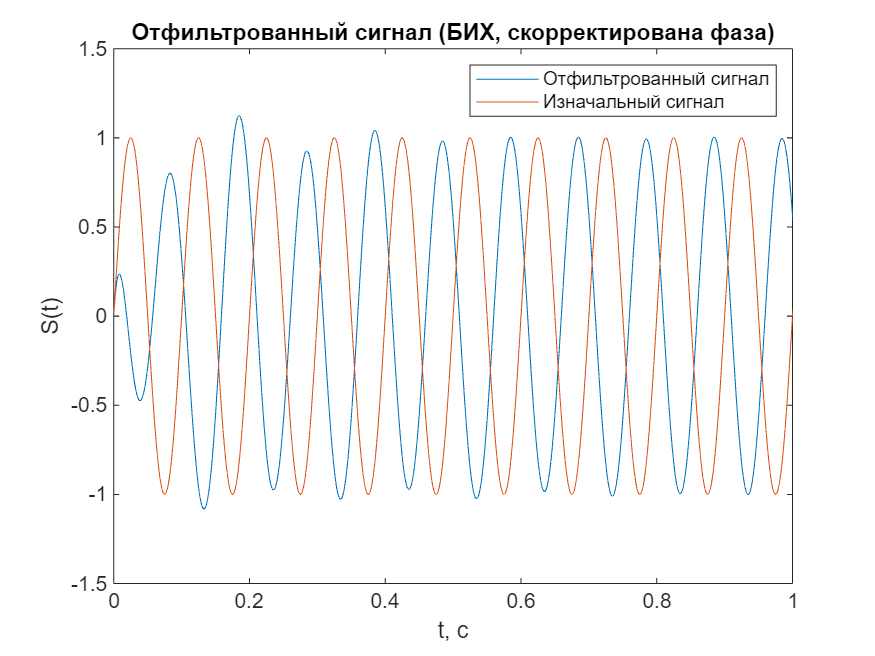

newS = filter(IIR,Sn);
plot(t, newS)
hold on
plot(t, A * sin(w * t))
hold off
title("Отфильтрованный сигнал (БИХ, скорректирована фаза)")
xlabel("t, с")
ylabel("S(t)")
legend("Отфильтрованный сигнал", "Изначальный сигнал")
xlim([0,1])

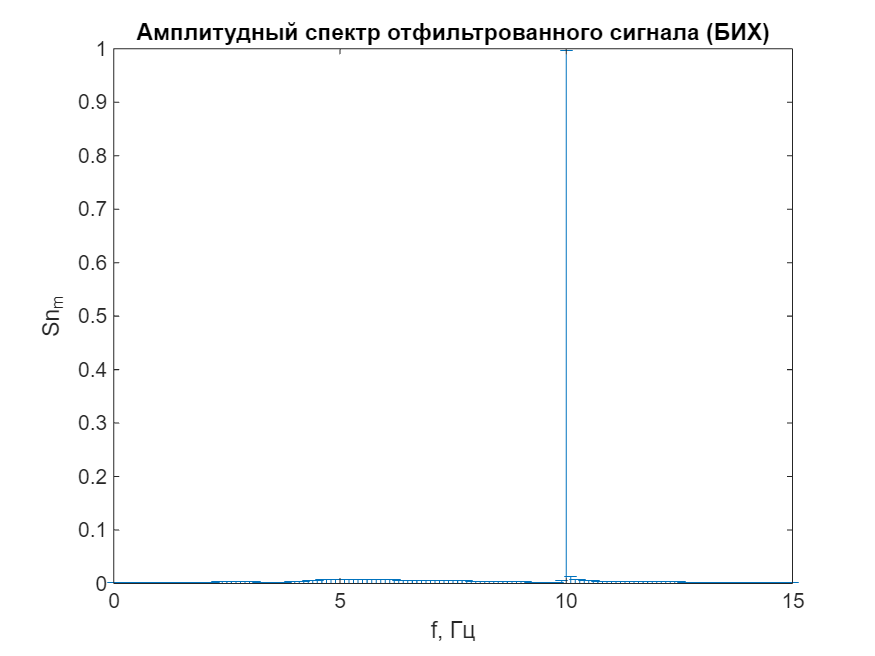

newS_FFT = fft(newS);
ampl = abs(newS_FFT) / length(newS_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.05; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(newS_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала (БИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

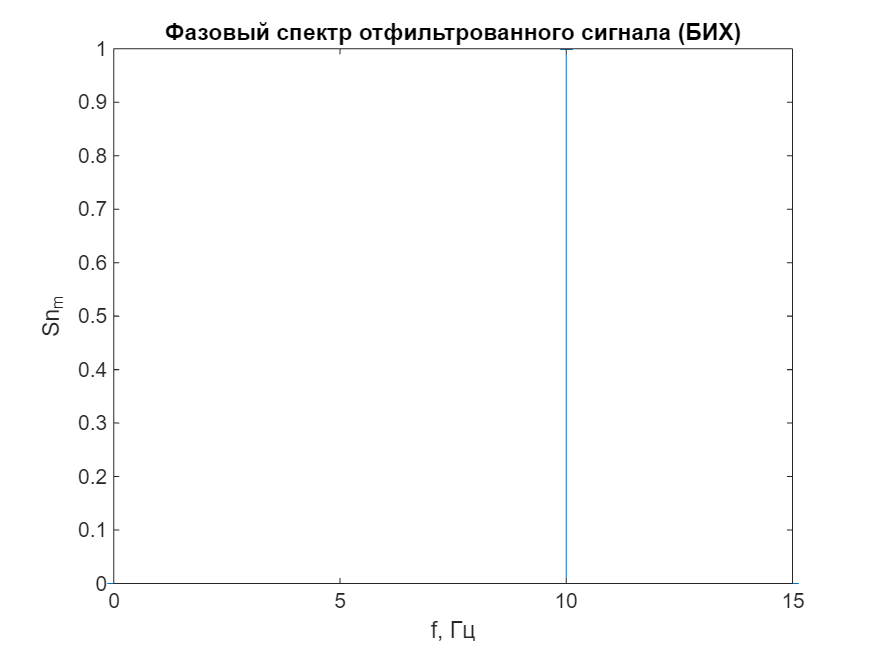

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала (БИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

7. Работа фильтров при амплитуде шума 100

nA = 100;
nw = 2 * pi * 1;
noise = nA * sin(nw * t);
Sn = S + noise;

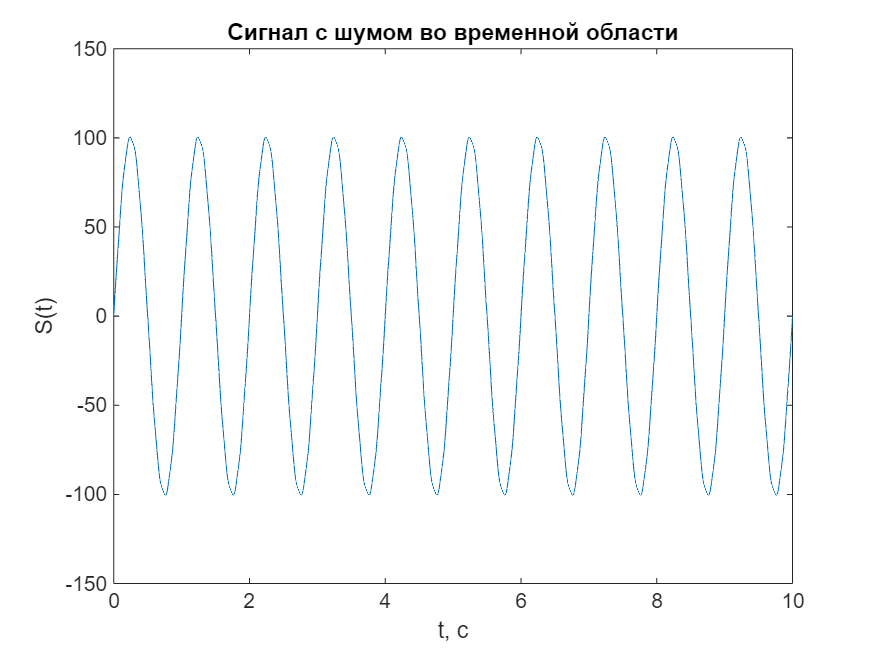

plot(t, Sn)
title("Сигнал с шумом во временной области")
xlabel("t, с")
ylabel("S(t)")

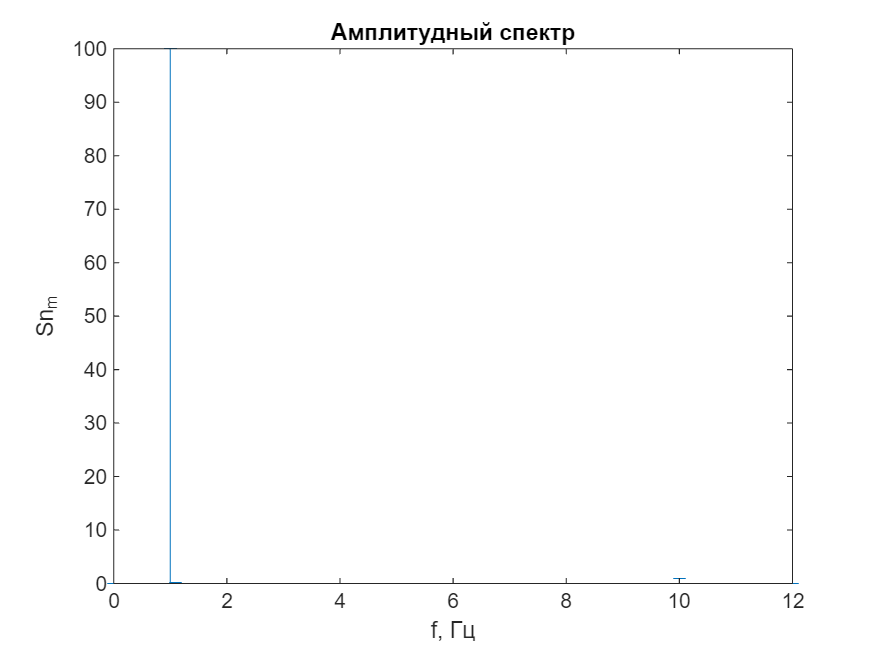

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn) * 2;
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,12])

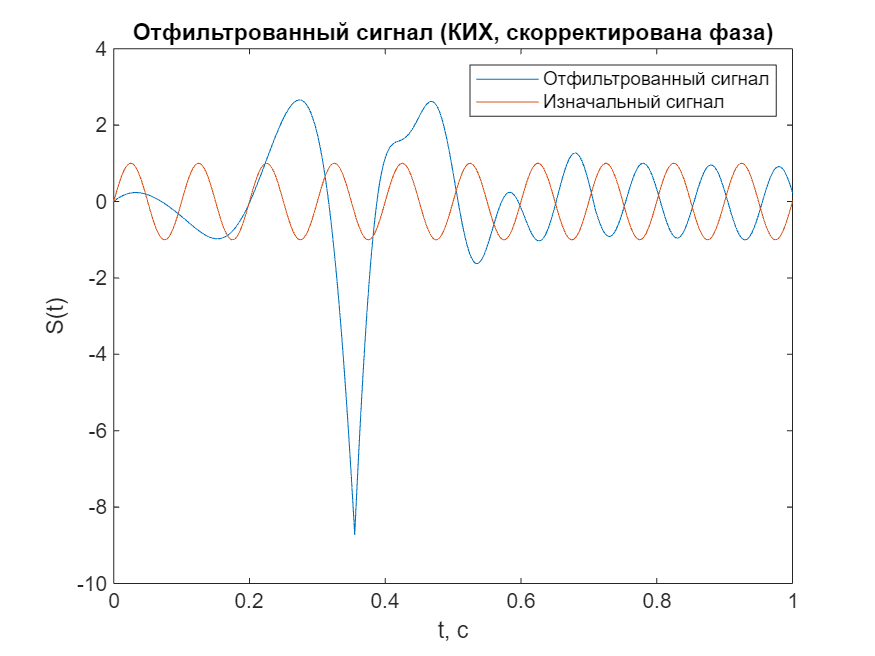

newS = filter(FIR,Sn);
plot(t, newS)
hold on
plot(t, A * sin(w * t))
hold off
title("Отфильтрованный сигнал (КИХ, скорректирована фаза)")
xlabel("t, с")
ylabel("S(t)")
legend("Отфильтрованный сигнал", "Изначальный сигнал")
xlim([0,1])

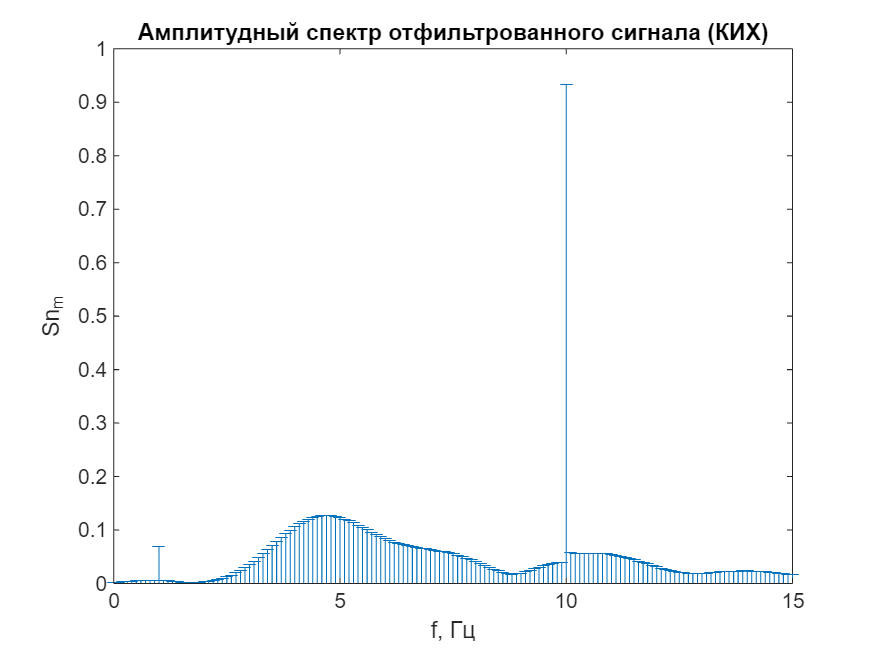

newS_FFT = fft(newS);
ampl = abs(newS_FFT) / length(newS_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.15; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(newS_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала (КИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

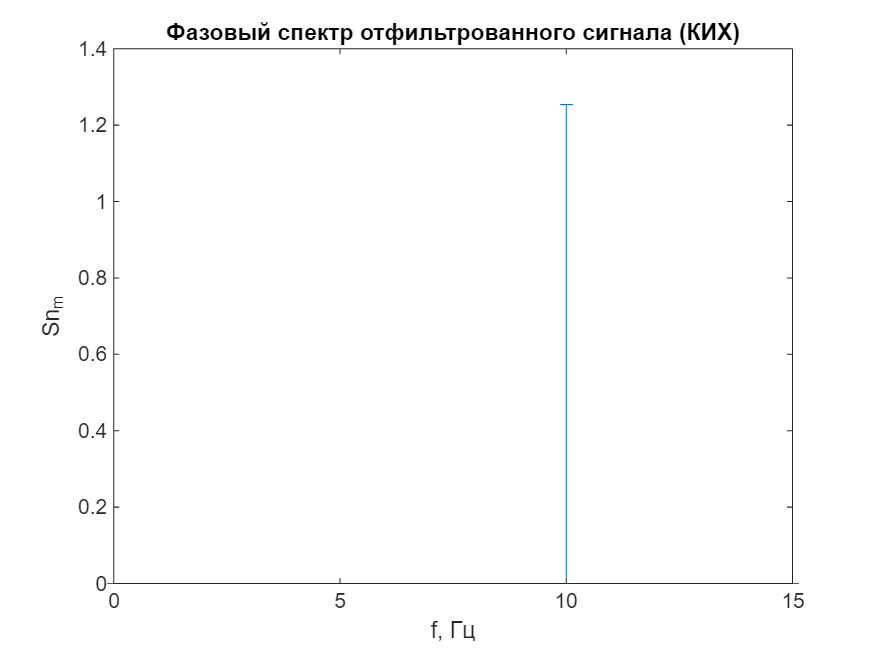

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала (КИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

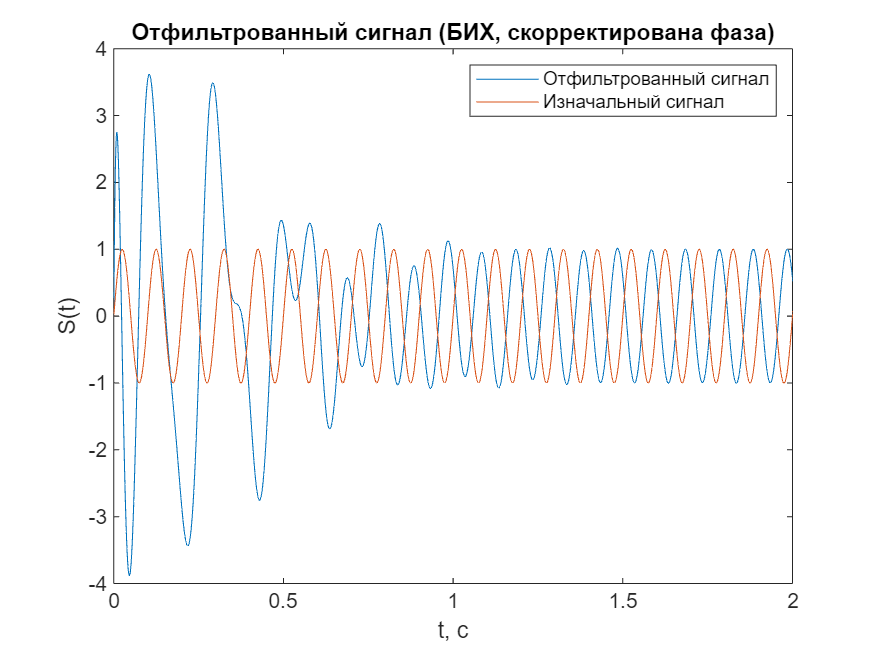

newS = filter(IIR,Sn);
plot(t, newS)
hold on
plot(t, A * sin(w * t))
hold off
title("Отфильтрованный сигнал (БИХ, скорректирована фаза)")
xlabel("t, с")
ylabel("S(t)")
legend("Отфильтрованный сигнал", "Изначальный сигнал")
xlim([0,2])

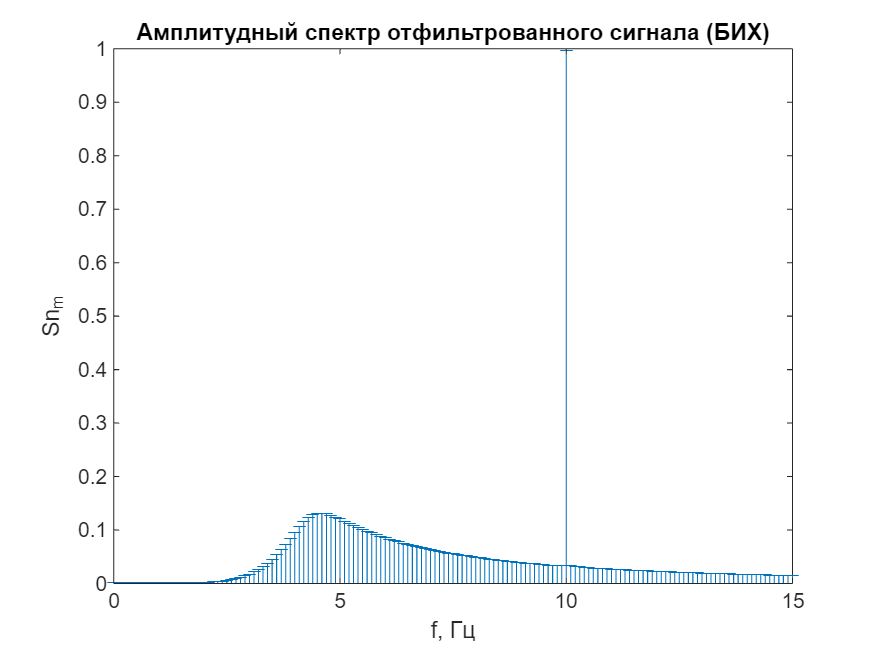

newS_FFT = fft(newS);
ampl = abs(newS_FFT) / length(newS_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.05; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(newS_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала (БИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])

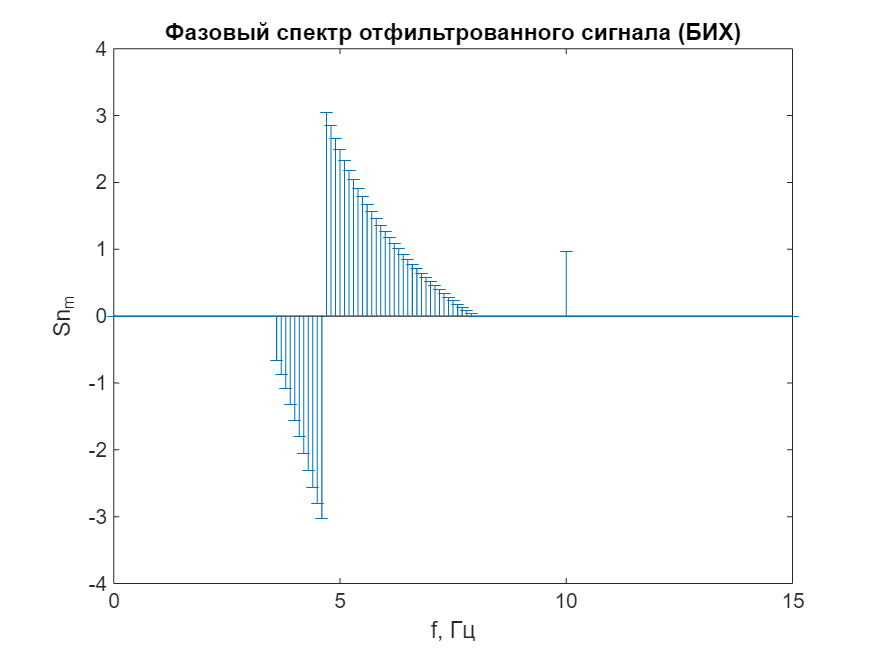

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала (БИХ)")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,15])